# Lab #7 Final Project -- Filter Banks

## **Objectives**

- Learn how to integrate different filter types designed in the previous labs to create a set of filter banks to detect different breathing rates.

- Use statistics to measure the amount of energy passing through each band as the input signal frequency changes.

## Breathing Rate Detection System

In class we discussed development of a breathing rate detection system and outlined a set of functions in the form a high-level block diagram of the system.  The block diagram is shown in Figure 1 .  

*Figure 1  High Level Breathing Rate Detection System*

                       The block diagram includes a data acquisition subsystem, some signal preprocessing, a breathing rate detection function, warning logic and then finally an output for user signaling.  In this portion of the lab you will be further developing the breathing rate detection subsystem which includes a series of various types of filters, lowpass, highpass and bandpass combined to detect different rates of breathing.

As a patient is breathing their breath flows back and forth across the temperature sensor and warms and cools the temperature sensor.  Breathing can be detected by observing the signal output from the temperature sensor.  The output of a regular breathing rate appears sinusoidal in nature where the frequency of the sinusoid is the rate of breathing period.  The breathing rate can be determined from the frequency of the sinusoid. 

The breathing rate detection subsystem is shown in the block diagram in Figure 2. The system consists of three filters, one for low rate detection, normal rate detection and for high rate detection. The output of each of these filters is followed by a signal detection block. The filters discriminate between the different rates by passing only signals that fall within the desired range or band.  The signal detectors at the output of each filter detect the amount of energy in each of those frequency bands. 

 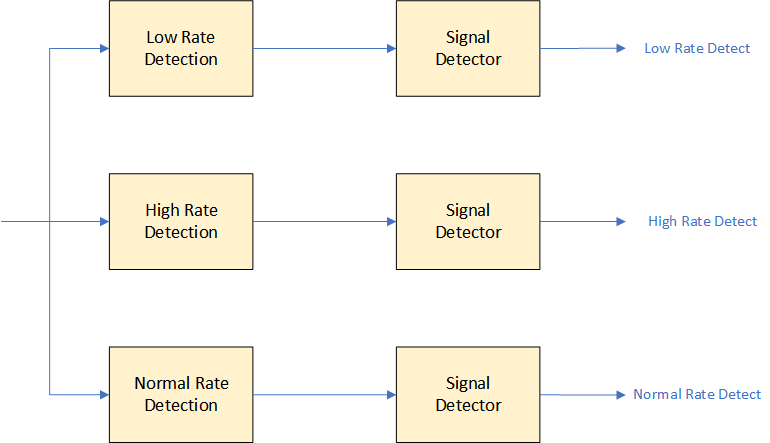

*Figure **2*  *Breathing Rate Detection Subsystem*

Ultimately the output of the signal detectors will be compared to determine within what frequency range the energy lies. This will determine whether the user is warned of a rate that is outside of the acceptable limits. 

## Choice of Filter Cutoff Frequencies

The normal breathing rate for children is within a range of 12 to 40 breaths per minute.  A rate of breathing above this value above can indicate an abnormal condition such as pneumonia.

A rate below this value could indicate another abnormal condition or a failure of the equipment such as a broken wire or cable or sensor.

The breathing rate detection subsystem must detect breathing rates within three different ranges. It must detect whether it is below 12 breaths per minute, between 12 and 40 breaths per minute or above 40 breaths per minute. 

## Structure of the C-Code for Filter Banks

The code base for the final project is in myCourses and called "Final_Project_Code_Base.ino".  In the code there is a function called IIR_Generic.  It is an implementation of an IIR filter using second order sections.  Use this starter function as you build your filter bank.  You can copy this function and rename it to create multiple filters.  You can use the MATLAB scripts to generate the C-code for declaring variables and for initializing coefficient values.

In the block diagram the filters are in parallel and their input is the same value from the output of the signal procesing section (equalizer and noise filter).  As new samples enter the system, eventually each filter will be called once each time a new sample enters the system. The new sample will be processed by each filter.

To detect how much energy is passing through each filter statistics are computed for the output of each of the filters using the running stats function.  The statistics function is run for each output of the filter and a running mean, variance and standard deviation are computed.  The running stats function has been modified to restart after every 100 input values and to hold the output value at the last computation of the standard deviation.  This is done to allow a quick recovery when the energy output changes.  A simple flow diagram of the C-Code is shown in Figure 3 below.

To begin, design and test one filter at a time by designing and testing each filter individually.  Create a new function for each filter.  Once all the filters have been verified, then the code will be modified so that they can run all at the same time.  Statistics will also be computed to determine how much energy is in each band.  You will later use the standard deviation outputs of the statistic calculations to determine which bands contain energy.

NOTE:  The filter coefficients that are in the starter code are not the correct values.  You will have to determine the correct values for your design.

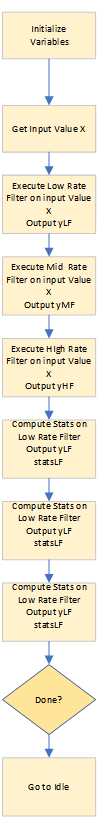 

*Figure **3** Simple Flow Diagram for Breathing Rate Detection*                        

## MATLAB and C starter code 

The MATLAB scripts that create the filter coefficients and the Arduino starter C code is available in myCourses.  Be sure to download the latest version of CaptureArduinoData.m as that has improvements for use with large sample numbers.

## Low-Range Breathing Rate Detector

The low breathing rate detector is required to detect energy below a rate of 12 breaths per minute. During the system design it was decided that a low pass filter will be used to pass signals with rates below 12 breaths per minute and attenuate signals with rates higher than that.

Design an IIR low pass filter using second order sections that has a corner frequency of 12 breaths per minute with a transition bandwidth of approximately 5 breaths per minute or less.  The transition region is the frequency range between magnitudes of about 0.9 to 0.1 of the filter output.  Adjust the order of the filter to achieve the desired transition bandwidth.  You can iterate the filter design using the MATLAB tools and the frequency response graph it creates.  Use the minimum order filter necessary to achieve the transition bandwidth.  Use a Chebyshev filter to provide fast filter roll-off.  Use a ripple of 0.5 dB or less.  

Use the MATLAB tools that you used in the last exercise to design the filter and compute the recursion coefficients for the filter.

Copy the IIR_Generic filter function and rename it appropriately.  Copy the MATLAB generated C-Code variable declarations and variable definitions into the appropriate section of the C-Code as was done in Lab 6.

Then verify your filter impulse response in your C-Code using the impulse response input.  Capture at least 512 samples of the impulse response data using MATLAB.  Plot your filter response by computing the FFT of the impulse response in MATLAB.  Be sure to set up the printArray[] variable in the C-code to print out the correct values to the serial monitor.  You also must set the variable numValues correctly.  No header line will be printed to the monitor so you need to know what each column represents.

Test your filter in the time domain on the Arduino by changing the input to the filter to the test vector generator to create sinusoids within the passband of the filter in the transition region, and above the passband of the filter. Capture at least 3600 samples of the output.  Use the 'GraphDelay' parameter in the function CaptureArduinoData to avoid problems with the serial port overflow.

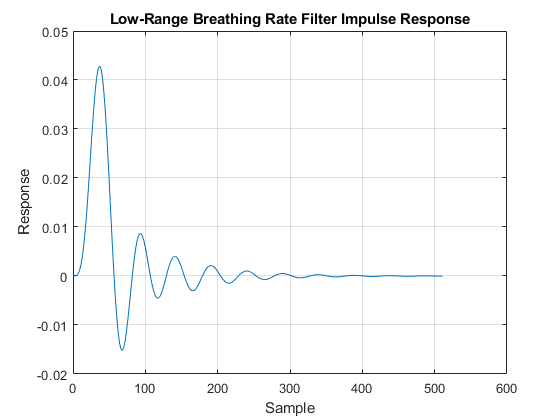



%
%  Capture the impulse response of the filter from the Serial Monitor.
%  Then plot the frequency response of the filter in MATLAB
%

%  SOLUTION
fileName = 'Low Rate Detection Filter.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
filter_response = outData(:,2);

% Impulse Response
figure
plot(sample, filter_response)
grid on
title('Low-Range Breathing Rate Filter Impulse Response')
xlabel('Sample')
ylabel('Response')

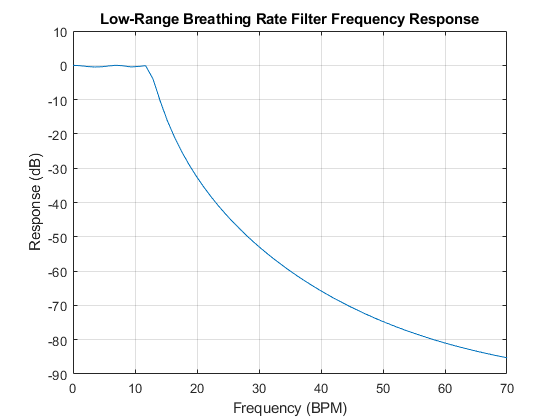


% Frequency Response
FFT_response = fft(filter_response, 512);
response_dB = 20*log10(abs(FFT_response));
breathing_rate = [0:511]/512 * 10 * 60;

figure
plot(breathing_rate, response_dB)
grid on
title('Low-Range Breathing Rate Filter Frequency Response')
xlabel('Frequency (BPM)')
ylabel('Response (dB)')
xlim([0,70])

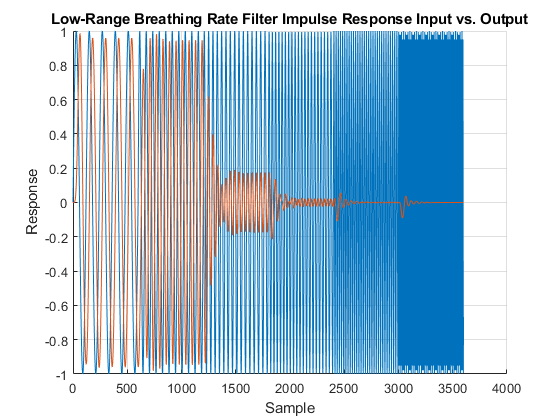


%
%  Capture the input and the output of the test vector generator to verify
%  that the filter is working correctly in the time domain.  Plot the input
%  and output time sequences.
%

%  SOLUTION
fileName = 'Low Rate Detection Filter In vs Out.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
input = outData(:,2);
output = outData(:,3);

figure
hold on
plot(sample, input)
plot(sample, output)
grid on
title('Low-Range Breathing Rate Filter Impulse Response Input vs. Output')
xlabel('Sample')
ylabel('Response')

## Mid-Range Breathing Rate Detector

The mid-range breathing rate detector is required to detect energy above a rate of 12 breaths per minute but below a rate of 40 bpm. A band pass filter will be used pass signals with rates above 12 breaths per minute and below 40 bpm.  Signals with energy outside of this range will be attenuated.

Design an IIR bandpass filter using second order sections that has a lower corner frequency of 12 breaths per minute and an upper corner frequency of 40 breaths per minute.  The transition bandwidth of each corner should be less than about 5 breaths per minute.  This should be easily achievable with a reasonable order filter.

The transition bandwidth is the frequency range between magnitudes of about 0.9 to 0.1 of the filter output. Adjust the order of the filter to achieve the desired transition bandwidth.  Use the minimum order filter necessary to achieve the transition bandwidth.   Use a Chebyshev filter to provide fast filter roll-off.  Use a ripple of 0.5 dB or less.  

Use the MATLAB tools that you used in the last exercise to design the filter and compute the recursion coefficients for the filter.

Copy the IIR_Generic filter function and rename it appropriately.  Copy the MATLAB generated C-Code variable declarations and variable definitions into the appropriate section of the C-Code as was done in Lab 6.

Then verify your filter impulse response in your C-Code using the impulse response input.  Capture at least 512 samples of the impulse response data using MATLAB.  Plot your filter response by computing the FFT of the impulse response in MATLAB.  Be sure to set up the printArray[] variable in the C-code to print out the correct values to the serial monitor.  You also must set the variable numValues correctly.  No header line will be printed to the monitor so you need to know what each column represents.

Test your filter in the time domain on the Arduino by changing the input to the filter to the test vector generator to create sinusoids within the passband of the filter in the transition region, and above the passband of the filter. Capture at least 3600 samples of the output.  Use the 'GraphDelay' parameter in the function CaptureArduinoData to avoid problems with the serial port overflow.

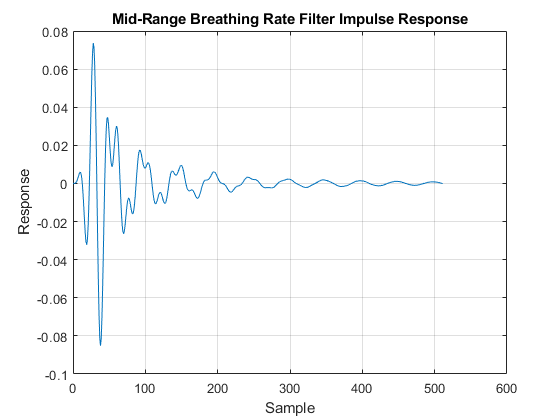

%
%  Capture the impulse response of the filter from the Serial Monitor.
%  Then plot the frequency response of the filter in MATLAB
%

%  SOLUTION
fileName = 'Mid Rate Detection Filter.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
filter_response = outData(:,2);

% Impulse Response
figure
plot(sample, filter_response)
grid on
title('Mid-Range Breathing Rate Filter Impulse Response')
xlabel('Sample')
ylabel('Response')

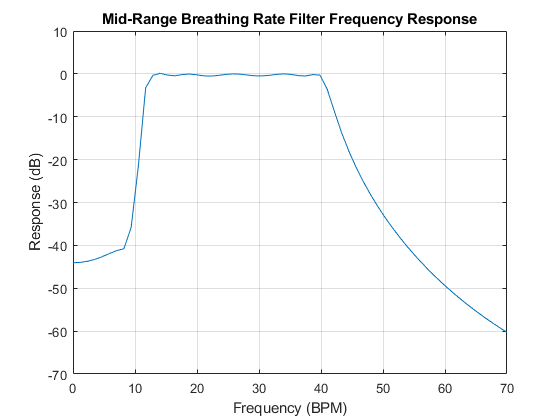


% Frequency Response
FFT_response = fft(filter_response, 512);
response_dB = 20*log10(abs(FFT_response));
breathing_rate = [0:511]/512 * 10 * 60;

figure
plot(breathing_rate, response_dB)
grid on
title('Mid-Range Breathing Rate Filter Frequency Response')
xlabel('Frequency (BPM)')
ylabel('Response (dB)')
xlim([0,70])

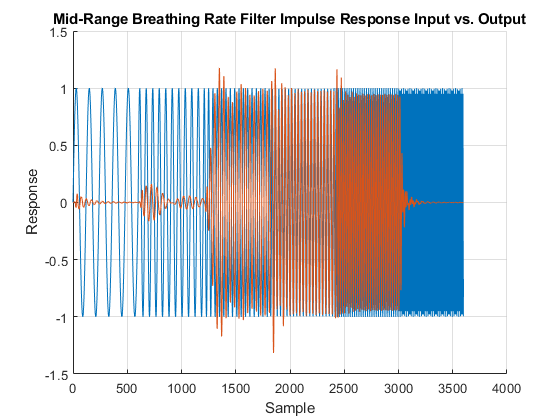


%
%  Capture the input and the output of the test vector generator to verify
%  that the filter is working correctly in the time domain.  Plot the input
%  and output time sequences.
%

%  SOLUTION
fileName = 'Mid Rate Detection Filter In vs Out.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
input = outData(:,2);
output = outData(:,3);

figure
hold on
plot(sample, input)
plot(sample, output)
grid on
title('Mid-Range Breathing Rate Filter Impulse Response Input vs. Output')
xlabel('Sample')
ylabel('Response')

## High-Range Breathing Rate Detector

The high-range breathing rate detector is required to detect energy above a rate of 40 breaths per minute. A high pass filter will be used pass signals with rates above 40 breaths per minute.  Signals with energy below this frequency range will be attenuated.

Design an IIR high pass filter using second order sections that has an upper corner frequency of 40 breaths per minute.  The transition bandwidth of the filter should be less than about 5 breaths per minute.  This should be easily achievable with a reasonable order filter.

The transition bandwidth is the frequency range between magnitudes of about 0.9 to 0.1 of the filter output. Adjust the order of the filter to achieve the desired transition bandwidth.  Use the minimum order filter necessary to achieve the transition bandwidth.    Use a Chebyshev filter to provide fast filter roll-off.  Use a ripple of 0.5 dB or less.  

Use the MATLAB tools that you used in the last exercise to design the filter and compute the recursion coefficients for the filter.

Copy the IIR_Generic filter function and rename it appropriately.  Copy the MATLAB generated C-Code variable declarations and variable definitions into the appropriate section of the C-Code as was done in Lab 6.

Then verify your filter impulse response in your C-Code using the impulse response input.  Capture at least 512 samples of the impulse response data using MATLAB.  Plot your filter response by computing the FFT of the impulse response in MATLAB.  Be sure to set up the printArray[] variable in the C-code to print out the correct values to the serial monitor.  You also must set the variable numValues correctly.  No header line will be printed to the monitor so you need to know what each column represents.

Test your filter in the time domain on the Arduino by changing the input to the filter to the test vector generator to create sinusoids within the passband of the filter in the transition region, and above the passband of the filter. Capture at least 3600 samples of the output.  Use the 'GraphDelay' parameter in the function CaptureArduinoData to avoid problems with the serial port overflow.

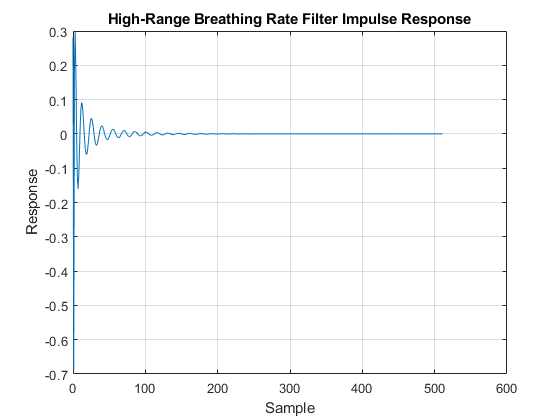

%
%  Capture the impulse response of the filter from the Serial Monitor.
%  Then plot the frequency response of the filter in MATLAB
%

%  SOLUTION
fileName = 'High Rate Detection Filter.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
filter_response = outData(:,2);

% Impulse Response
figure
plot(sample, filter_response)
grid on
title('High-Range Breathing Rate Filter Impulse Response')
xlabel('Sample')
ylabel('Response')

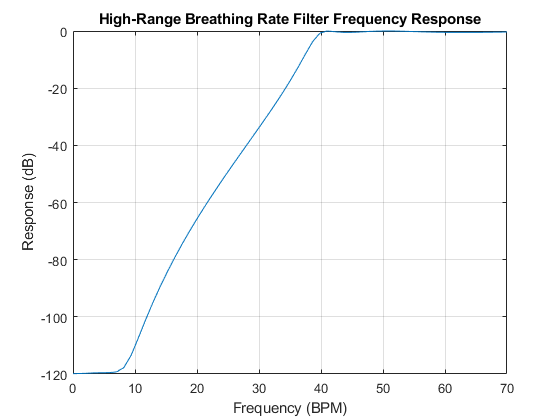


% Frequency Response
FFT_response = fft(filter_response, 512);
response_dB = 20*log10(abs(FFT_response));
breathing_rate = [0:511]/512 * 10 * 60;

figure
plot(breathing_rate, response_dB)
grid on
title('High-Range Breathing Rate Filter Frequency Response')
xlabel('Frequency (BPM)')
ylabel('Response (dB)')
xlim([0,70])

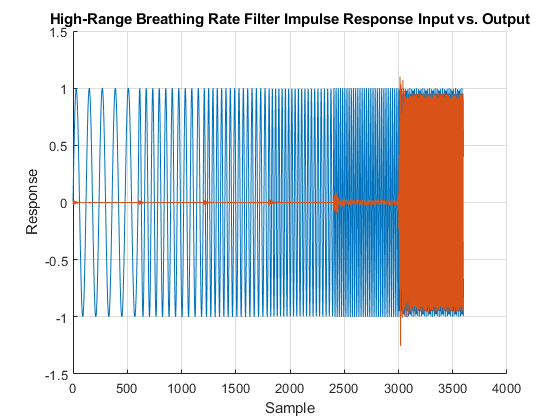


%
%  Capture the input and the output of the test vector generator to verify
%  that the filter is working correctly in the time domain.  Plot the input
%  and output time sequences.
%

%  SOLUTION
fileName = 'High Rate Detection Filter In vs Out.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
input = outData(:,2);
output = outData(:,3);

figure
hold on
plot(sample, input)
plot(sample, output)
grid on
title('High-Range Breathing Rate Filter Impulse Response Input vs. Output')
xlabel('Sample')
ylabel('Response')

## Running all three filters in parallel

In the final application we'll want to run all three filters in parallel.  This is simply done by calling each function in succession with the same input value.  Use the test vector generator as the input to the filters.  

Comment back in the call to each of the filter function.  Rename the the output variable something appropriate (you will have to declared these variables in the setup portion of the code.  Some are already declared if you want to use those names).  Also modify the printArray and numValues so that all three outputs will be writtien to the serial port.

Capture data for all three outputs running in parallel and plot their outputs in MATLAB to make sure that they all run correctly when driven in parallel

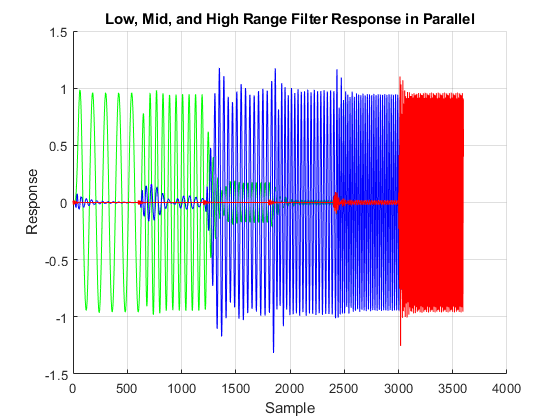

%
%  Capture the input and the output of the test vector generator to verify
%  that the filter is working correctly in the time domain.  Plot the input
%  and output time sequences.
%

%  SOLUTION
fileName = 'Parallel Filters.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
input = outData(:,2);
low_resp = outData(:,3);
mid_resp = outData(:,4);
high_resp = outData(:,5);

figure
hold on
% plot(sample, input,'c')
plot(sample, low_resp,'g')
plot(sample, mid_resp,'b')
plot(sample, high_resp,'r')
grid on
title('Low, Mid, and High Range Filter Response in Parallel')
xlabel('Sample')
ylabel('Response')

## Detecting Energy at the Filter Outputs

In the breathing rate detector subsystem block diagram, there is an energy detector shown at the output of each filter.

This energy detector is measuring the standard deviation of the signal at the output of the filter. If there is energy passing through the filter, then the standard deviation of the signal will be large.  If there is no energy in the filter, then the standard deviation of the signal will be small.

The standard deviation output of each filter bank can be compared to one another to determine which filters have the most energy passing through to determine the breathing rate of the patient.  

In the next part of the lab, logic will be applied to the energy outputs to decide if the breathing rate is within normal limits or above or below the normal range.  Then the user can then be alerted to a dangerous condition. 

The C-Code function getStats is used to compute the running statistics of the signal.  The running values are stored in three variable structures one for each filter output.  These are statsLF, statsMF and statsHF.  These variable structures contain four variables, the current time tick for the stats function, the running mean, variance and standard deviation as shown in the variable declaration below.      

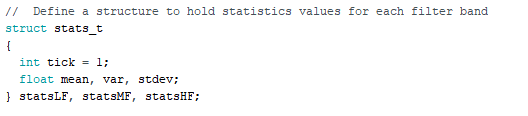                  

The variables in a structure are accessed by using the dot (.) operator.  If the structure name is statsLF and I want to get the "mean" value I would use statsLF.mean.

By passing this structure each time only one function need be written and the code becomes more modular and reusable.  It also takes up less overall code space in memory.

Here is a snip of the getStats function

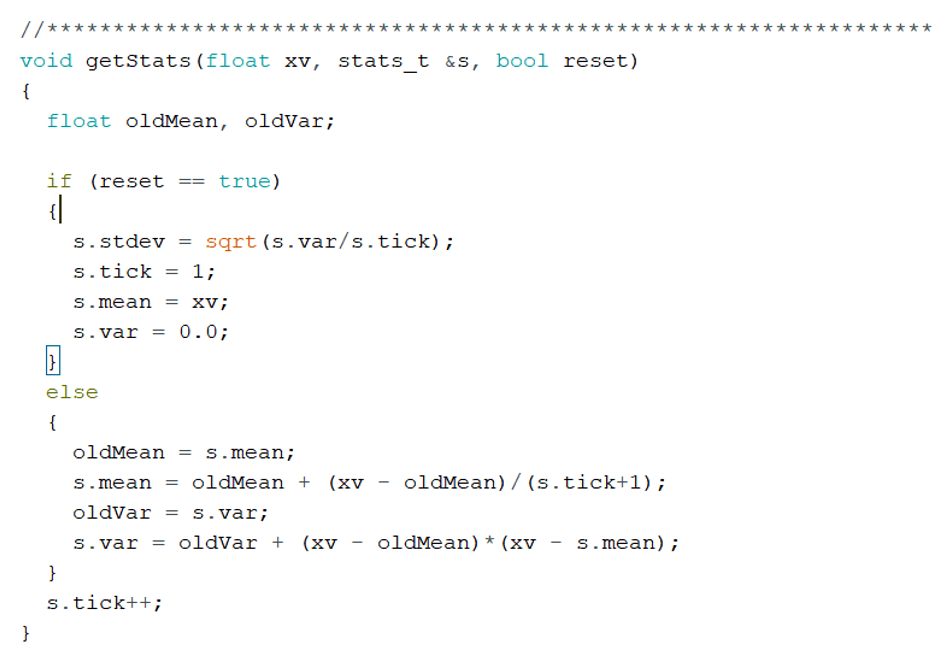

Here is how the function is called from the main routine.  This is a resettable statistics routine in that every 100 samples, the running values are restarted to make them converge more quickly.  Passing the function a boolean statsReset tells the function to compute the final standard deviation value and reset the running values.  The boolean is calculated by taking the looptick value mod 100.

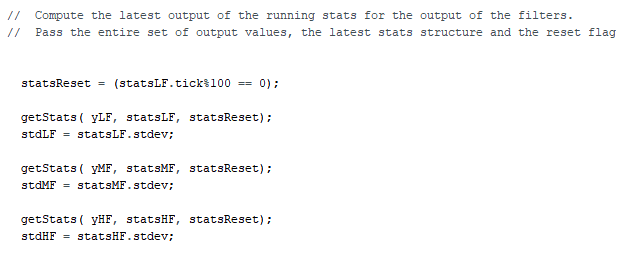

The getStats function is called for the output of each filter with the output for that band as one of the inputs to the function.  The function returns the statistics structure for that band which contains the running values of the mean and variance.

Test all three filters and running standard deviation calculations running in parallel by commenting in all three filter function calls.  Then comment in the call to all three statistics functions.

Modify the printArray so that all the values that you want to capture are saved in the array.  Change the variable numValues to the number of variables in the array.

Execute the code using the test vector generator as the input signal.  

Make plots of the statistics output for each band (three plots).  

An example plot for the low range band is shown in Figure 6.  

What do you observe about the signals out of each filter as the input signal frequency changes?

What do you observe about the standard deviation output for each band as the input signal frequency changes?

How might you use the standard deviation to determine which filter has energy passing through it?

Include the three plots of the filter output and standard deviation along with answers to any questions in your report.

 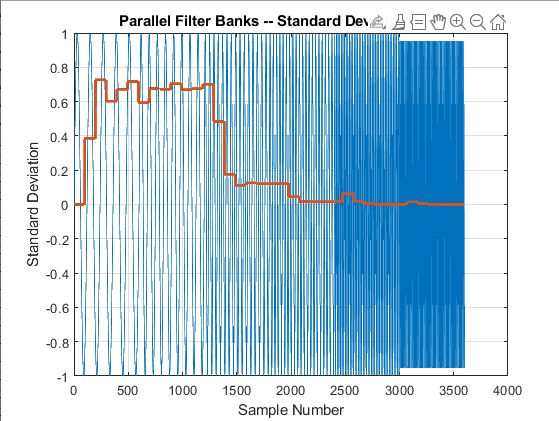

*Figure **6*  *Example of the Filter Output and Statistics Output for the Low-Range Detector*

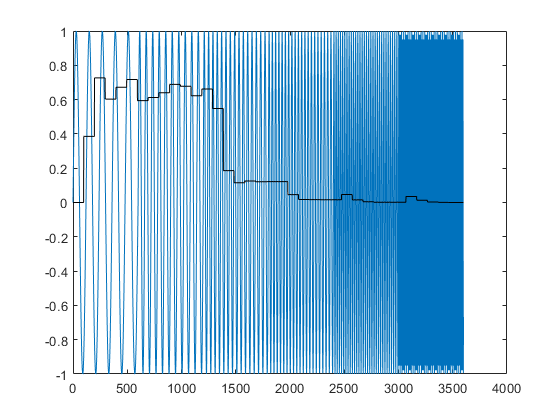

%
%  Capture the output of the statistics function and plot the three
%  standard deviations
%


%  SOLUTION
fileName = 'Running Stats.mat';
load(fullfile(pwd, fileName));
sample = outData(:,1);
input = outData(:,2);
stats_low = outData(:,3);
stats_mid = outData(:,4);
stats_high = outData(:,5);

figure
% low
plot(sample, input)
hold on
plot(sample, stats_low,'k')
% mid
hold off

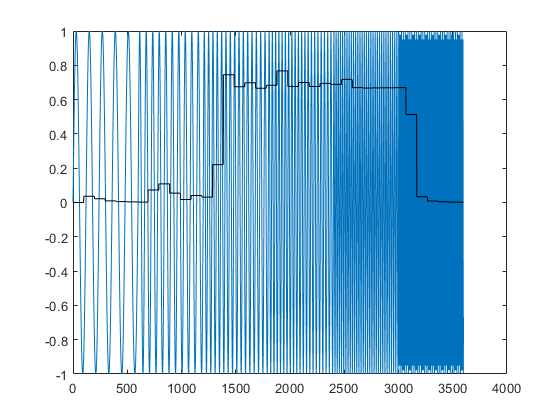

plot(sample, input)
hold on
plot(sample, stats_mid,'k')
% high
hold off

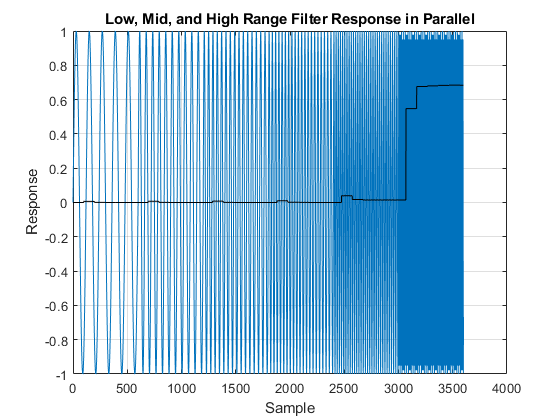

plot(sample, input)
hold on
plot(sample, stats_high,'k')

grid on
title('Low, Mid, and High Range Filter Response in Parallel')
xlabel('Sample')
ylabel('Response')

## Execution Time

Its important to make sure that the execution time is not so large that the processing cannot be completed before the next sample enters the system.  

Uncomment these sections of code to enable measuring execution times

## 

Also uncomment the line that prints the results of the time measurement

Run the code again with execution time measurement turned on.  Compute the percentage of the sample time used by the filter and statistics process.  There is more processing that has to be done by the system, but we'll want to make sure that we are not in trouble this early in the game

10 samples/sec

execution time = 1635.74 us

3600 samples

3600 / 10 = 360 seconds to finish data collection

1635.74 us / 360000 us = 0.00454

0.45%

## Report Requirements

There is no report due for this lab.  These last labs will build on one another culminating in the final project.  There will be a report and video demonstration due for the final lab.